# Binary Morphology

**Suggested Prework**

[MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted) – a free two-hour introductory tutorial to learn the essentials of MATLAB.

## What is Binary Morphology?

A binary image consists of only two intensity levels represented by `0` (black) and `1` (white). Image processing tasks, such as segmenting an image into foreground and background or detecting edges, typically result in a binary image output.

**Task.** Choose other options from the drop-down to view the different binary images available in this module. The function [`imread`](https://www.mathworks.com/help/matlab/ref/imread.html) reads an image from a graphics file format into the workspace. The function [`imshow`](https://www.mathworks.com/help/images/ref/imshow.html) displays an image in MATLAB.

AddExampleImagesToPath;
BW = imread("bot.png");                  % Read a binary image
figure;
imshow(BW)                                          % View the image in the output section
title("Input Image")

*Binary Morphology* refers to a group of operators and techniques used to perform specific shape-based operations on binary images. These operations typically use a simple predefined shape to probe into the structures in a binary image. This probing shape, which you can interpret as another binary image, is often referred to as a *structuring element*. These set of operators were originally developed by treating the input binary image and the structuring elements as mathematical sets. In this module, you will learn about some of the most widely used operations in this category and their practical uses in image processing.

 **NOTE: **This script contains several illustrative animations. Run one section at a time for best experience. Instructions and controls will help you navigate through each section. 

Starting in R2021a, you can use playback controls to play, pause, or replay an animation at different speeds. These controls appear after completing the first run of any animation.

## Erosion and Dilation

Two fundamental operations form the basis for a majority of binary morphology—*erosion* and *dilation*. Using the language of set theory, one way of defining these operations is given below.

If$A$ and $B$ are sets in the integer space $Z^2$, where each element of the set is a 2-D vector of $\left(x,y\right)$ coordinates of all white pixels (by convention) in the corresponding binary image,

**Dilation** is defined as   $A\oplus B=\left\lbrace z:{\left(\hat{B} \right)}_z \cap A\not= \phi \right\rbrace$

${\left(\hat{B} \right)}_z$ denotes the reflection of $B$ about its origin displaced (translated) by $z$. 

Stated simply, the dilation of $A$ and $B$ is the set of all displacements $z$, such that $\hat{B}$ and $A$ overlap by at least one element. 

**Erosion **is defined as   $A\ominus B=\left\lbrace z:{\left(B\right)}_z \cap A^C \not= \phi \right\rbrace$

Simply put, the erosion of $A$ and $B$ is the set of all $z$, such that $B$ translated by $z$ is wholly contained in$A$.

Through these definitions, you can interpret dilation and erosion as *sliding* *neighborhood* operations analogous to [convolution](https://www.mathworks.com/academia/courseware/convolution-digital-signal-processing.html) (or spatial filtering). 

To develop an intuition of how erosion and dilation work in practice, visualize the operations in action in this section.

**Task.** Click **Animate** to view an illustration of morphological erosion or dilation with a square structuring element.

A = imread("squares.png");                          % Read a binary image (set A)

Create a basic square structuring element; that is, a square matrix containing only `1`s.

B = ones(3)                         % Create a square shape of 1s (set B)
 
BWMorph = animateMorphology("erosion",A,B);
figure;
imshow(BWMorph)
title("Output Image")

  ***Try***

- Use the slider to increase the size of the structuring element to `10`.

- Use the drop-down to select and perform dilation.

- Move the slider to decrease the size of the structuring element to `2`.

- Choose different images from the drop-down. Try eroding or dilating each with squares of different sizes and observe the effects.

 ***Reflect***

- *What overall effect do erosion and dilation respectively have on the objects (white pixel regions) in the image?*

- *How does changing the square size affect the outcome of the two operations? Why?*

## **Structuring Elements**

The set $B$ is commonly referred to as a *structuring element* in morphological operations. The shape and size formed by the set's elements describe the structuring element. This interpretation is helpful for practical application of morphological operations (that is, filtering image objects). 

The [`strel`](https://www.mathworks.com/help/images/ref/strel.html) function helps to automatically generate structuring elements of commonly used shapes and sizes in MATLAB.

**Task.** Click **Animate** to view an illustration of erosion or dilation with a different structuring element.

BW = imread("circles3.png");                 % Read a binary image
SE = strel("disk",2);      % Create a disk-shaped structuring element
nhood = SE.Neighborhood                            % Extract the neighborhood to see the shape     
 
BWMorph = animateMorphology("dilation",BW,nhood);
figure;
imshow(BWMorph)
title("Output Image")

  **Try**

- Use the slider to increase or decrease the radius of the disk and then click **Animate**.S

- Use the drop-down to select erosion and then click **Animate**.

- Refer to the documentation of [`strel`](https://www.mathworks.com/help/images/ref/strel.html) to learn how to create structuring elements in MATLAB.

 ***Reflect***

- *How does changing the element's shape to a disk affect the outcome of the two operations? Why?*

- *Why or when would you choose one shape over another?*

## Apply Erosion and Dilation

Use the functions [`imerode`](https://www.mathworks.com/help/images/ref/imerode.html) and [`imdilate`](https://www.mathworks.com/help/images/ref/imdilate.html) to erode or dilate an image in MATLAB.

***Task:**** Observe the code in the edit fields below. Click ****Run**** to view the output.*

BW = imread("bot.png");                         % Read a binary image
SE = strel("disk",1);                      % Create a structuring element
BWMorph = imerode(BW,SE);                 % Apply the morphological operation
 

figure;
imshowpair(BW,BWMorph,"montage")                        % View the input and output images side-by-side
title("Morphology Input (left) and Output (right)")

  **Try**

- Replace the code in the first edit field create a `"``line``"` structuring element with length `5` at an angle of `90` degrees. Refer to the documentation of [strel](https://www.mathworks.com/help/images/ref/strel.html) to find the correct syntax.

- Replace the code in the second edit field to perform dilation instead of erosion.

 ***Reflect***

- *Can you identify the morphological operation and the shape and size of the structuring element needed to produce each of the following outputs? Experiment with different combinations in this section to try and replicate these results.*

                A.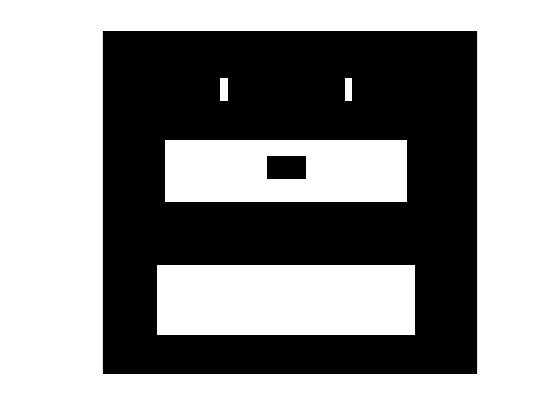B.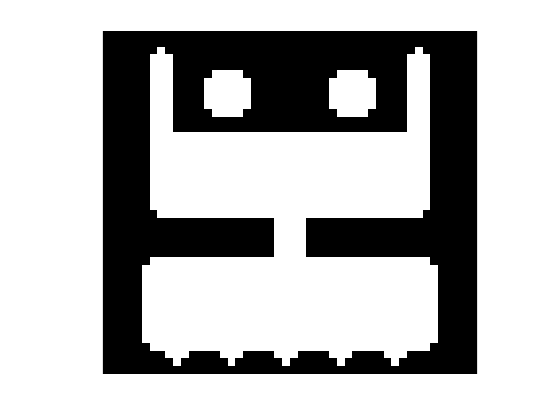

## **Logical and Relational Operations**

Pixels in a binary image can take one of two possible intensity values. This means that every pixel is like an ON/OFF switch and can be treated as a Boolean value. As you may have observed earlier in the module, such images are stored as a `logical` array in the workspace. You can apply the logical operations like AND(`&`), OR(`|`), and NOT(`~`) pixel-by-pixel to get another `logical` array, which you can also interpret as another binary image.

Relational operators `<`, `>`, `<=`. `>=`, `~=`, `== `are used to compare two arrays. They always return `logical` (`true` or `false`) values to indicate the whether the relationship holds. For example, suppose you compare a grayscale image arrays (pixel-by-pixel) using a relational operation (like `>=`) to a scalar value. In that case, the result is a `logical` array, which you can also interpret to be a binary image.

Combined with morphological operations, logical operations allow for more ways to create and process binary images to achieve different outcomes.

BW = imread("squares.png");             % Read an image
SE = strel("square",3)                  % Create a structuring element
BWDilated = imdilate(BW,SE);            % Dilate

figure;
imshowpair(BW,BWDilated,"montage")      % Visualize the input and output side-by-side
title("BW(left) and BWDilated(right)")

**Task.** In the edit field below, use the logical AND and NOT operations to exclude `BW` from `BWDilated`. (This is equivalent to the difference `BWDilated-BW`)

 
BWContour = false(size(BW));
imshow(BWContour)

**Combine morphology with logical operations to fill the region inside a boundary, starting with just one pixel that lies inside the boundary. **

First, create a binary image with one white pixel which lies inside the corresponding object boundary.

BW0 = false(size(BW));              % Create a logical array of 0s (false)
BW0(10,8) = true;                   % Set one of its elements to 1 (true) 
imshow(BW0)

Next, keep dilating and updating `BW0` to grow the region until it reaches the boundary `BWContour`.

**Task. **In the two edit fields below, replace the text with the correct pair of logical operators (`&`,`|`,`~`) between `BWGrow` and `BWContour` to restrict the region's growth within the boundary.

 
for k = 1:30       
    BWGrow = imdilate(BW0,SE);                                                    % Dilate BW0 with a small square structuring element       
    BWFilled = BWGrow ==  BWContour;         % Restrict the growth to lie within the boundary
    BW0 = BWFilled;                                                               % Update BW0 for the next iteration        
    imshow(BWFilled)                                                              % Display output in each iteration
    drawnow
end

***Reflect***

- *The *`for`* loop runs for an arbitrary number of predefined iterations. Is there a better way to determine when to stop?*

## **Practice Problem**

### **Contour Extraction I**

In this problem, you will use morphological erosion to extract the contours or the circular boundaries of coins in the given image.

I = imread("coins.png");                        % Read a binary image
figure;
imshow(I)        

 

As a first step, you must convert the grayscale coins image into a binary image, such that the brighter objects in the foreground (coins in this case) become completely bright (`1`) and the darker background becomes completely dark (`0`). To do this, you will threshold the gray intensities of the image.

a. **Task.** Use the slider to adjust the scalar threshold level between `0` and `255`. Try and ensure that all parts of the image containing coins are converted to white (`logical 1`) as best as possible.

BWCoins = I >189;        % Relational operation returns a logical output (binary image)
imshow(BWCoins);
title("Segmentation")

This is your segmentation result. A good segmentation will set you up to get more accurate coin boundaries at the end.

b.** Task. **Replace the code in the edit field below to create a disk-shaped structuring element with a radius of `1`. Use the `strel` function.

SE = false(3);

c.** Task.** Replace the code in the edit field below to erode the segmentation output `BWCoins` using the structuring element `SE`. Use the `imerode` function.

BWCoinsEroded = false(size(BWCoins));

d.** Task.** Replace the code in the edit field below to get the coins' boundaries by combining the binary images (`BWCoins` and `BWCoinEroded`) using the appropriate logical operators.This should give you a thin boundary surrounding the coins.

BWCoinsContour = false(size(BWCoins));
imshow(BWCoinsContour)

 ***Reflect***

- *Did you get the desired result? Or is there scope for some improvement?*

- *Can you get the coin boundaries by using dilation instead of erosion? How will the results differ?*

## Opening and Closing

With the two primitive operations (erosion and dilation) as a basis, you can now form other compound operations and algorithms. Two such widely used operations are morphological opening and closing as defined below. 

**Opening** is the erosion of an image followed by the dilation of the result with the same structuring element.

            
$$A\circ B=\left(A\oplus B\right)\ominus B$$


**Closing** is the dilation of an image followed by the erosion of the result with the same structuring element.

            
$$A\bullet B=\left(A\ominus B\right)\oplus B$$


Generally speaking, opening smooths object contours, breaks small bridges between regions, and removes tiny protrusions. Closing also smooths contours by filling gaps, bridges tiny gulfs between regions, and eliminates small holes. While erosion and dilation respectively shrink and expand the image foreground, opening and closing retain the overall sizes and structures of the image objects.

**Task.** Click **Animate** to view an illustrations for morphological opening and closing operations.

BW = imread("girl.png");                          % Read a binary image
SE = strel("disk",2);               % Create structuring element
nhood = SE.Neighborhood                                     % Extract the neighborhood to inspect 
 
BWMorph = animateMorphology("opening",BW,nhood);
figure;
imshow(BWMorph)
title("Output Image")

  **Try**

- To perform the closing operation, switch the order of dilation and erosion by using the drop-downs.

- Change the radius of the disk structuring element by using the slider.

 ***Reflect***

- *In what ways is the result of opening different from that of only eroding the input image?*

- *In what ways is the result of closing different from that of only dilating the input image?*

## Apply Opening and Closing

The functions [`imopen`](https://www.mathworks.com/help/images/ref/imopen.html) and [`imclose`](https://www.mathworks.com/help/images/ref/imclose.html) directly apply these operations to an image.

BW = imread("bot.png");                      % Read a binary image
SE = strel("disk",1);                              % Create a structuring element
BWMorph = imopen(BW,SE);                         % Apply the morphological operation
 
figure;
imshowpair(BW,BWMorph,"montage")                        % View the input and output images side-by-side
title("Morphology Input (left) and Output (right)")

  **Try**

- Use a different structuring element by replacing the code in the appropriate box.

- Replace the code in the appropriate box with the function to perform closing.

 ***Reflect***

- *Can you identify the morphological operation and the shape and size of the structuring element needed to produce each of the following outputs? Experiment with different combinations in this section to try and replicate these results.*

                A.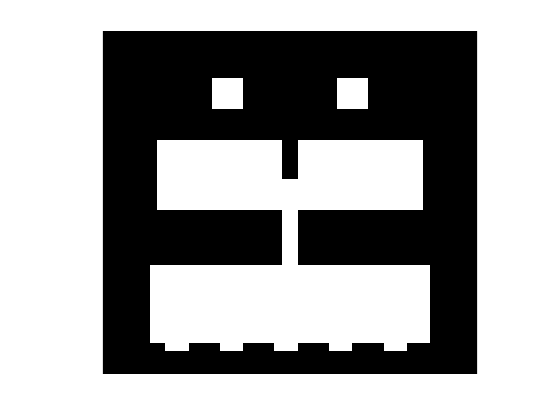B.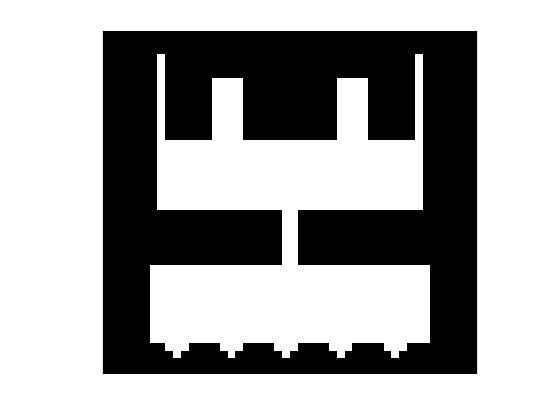

## **Practice Problems**

### **Contour Extraction II**

In Contour Extraction I, you applied basic morphology and logical operations to get the boundaries of coins. The first step to do this was to binarize the image to get the coins as foreground (white) and everything else as background (black).

a. Read the image and apply a threshold to the gray intensities to get a binary mask of coins.

I = imread("coins.png");                          % Read a binary image
figure;
imshow(I)
BWCoins = I > 85;         % Relational operation returns a logical output (binary image)
imshow(BWCoins)                                     

b.** Task. **To "close" any small holes in the coins (foreground), apply the closing operation to `BWCoins` with a disk of radius `1` `o`r `2`. Replace the code in the edit fields below with the appropriate function calls.

SE = false(2);                        % Create a structuring element
BWCoinsClosed = false(size(BWCoins));             % Closing
imshow(BWCoinsClosed)

c. **Task. **To remove any tiny specks of white in the black background, apply the opening operation to `BWCoinsClosed` with a disk of radius `1` `o`r `2`. Replace the code in the edit fields below with the appropriate function calls.

SE = false(2);                        % Create a structuring element
BWCoinsOpened = false(size(BWCoins));             % Opening
imshow(BWCoinsOpened)

d. Extract the contours by first eroding `BWCoinsClosed` with a tiny disk element and then excluding the eroded result from `BWCoinsClosed`.

SE = strel("disk",1)                              % Create a structuring element
BWCoinsEroded = imerode(BWCoinsOpened,SE);        % Erosion
imshow(BWCoinsEroded)
               
BWContour = BWCoinsOpened & ~BWCoinsEroded;       % Retain the boundaries of the coins by excluding the eroded coins from the closed coins
imshow(BWContour)

***Reflect***

- *Depending on the scalar threshold used for segmenting the coins, your image may have either holes or noisy specks or both. Try increasing or decreasing the value using the slider to observe the effects of opening and closing operations in each case.*

### **Identifying Nickels**

In this exercise, you will use morphological and logical operations to separate the nickels from the dimes in `coins.png`. 

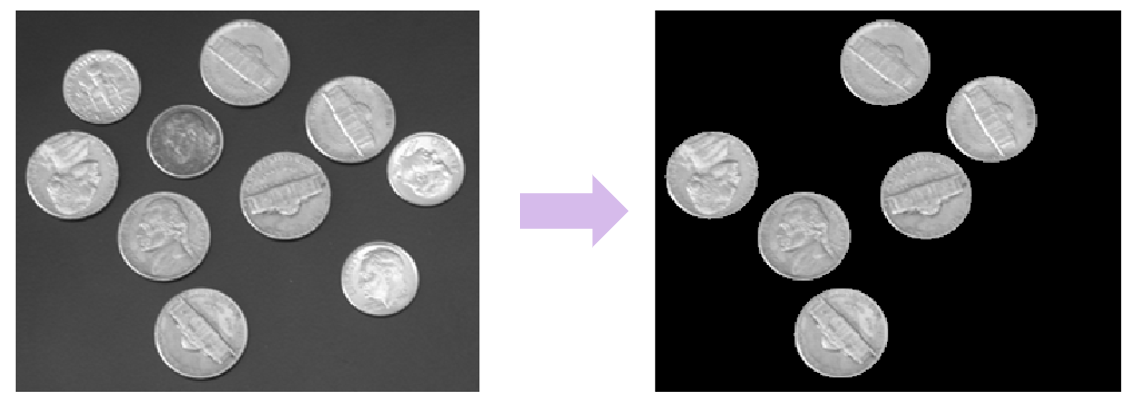

 ***Reflect***

- *Before following the instructions given below for this exercise, think of how you might approach this problem using morphological operations. What are the steps you will use to separate the nickels?*

a. Measure the sizes (radii) of the two types of coins in the image. Select an integer-valued radius for a disk-shaped structuring element in between these two. 

**Task. **Click** Measure coins** button**.** A small window containing the image and several tools will open. Use the **Distance** tool   to measure the approximate diameters of the two different coins. You can zoom in and out to get a better resolution. Enter the values in the next section.

 
I = imread("coins.png");
imtool(I)

Use this section to enter the measurements from step a, choose the size of the structuring element for the next step, and validate your estimation.

radiusSmall = 0/2
radiusBig = 0/2
radiusSE = 0;

disp("Use the dropdown to check if radius is correct")

b.** Task.** Replace the code in the edit fields below to apply morphological opening to `BWCoins` with the disk-shaped structuring element of radius `radiusSE` determined in step a.

I = imread("coins.png");
BWCoins = I > 100;

SE = false(3);          
BWCoinsOpened = false(size(BWCoins));

imshow(BWCoinsOpened)

c.** Task. **Replace the code in the edit fields below to dilate `BWCoinsOpened` with a small disk-shaped structuring element. Pick a radius such that the foreground objects (white pixels) in the dilated image will wholly encompass the regions containing nickels without any of the shapes overlapping.

SE = false(3);
BWCoinsDilated = false(size(BWCoins));
imshow(BWCoinsDilated)

d.** Task. **Use a logical operator to combine `BWCoinsDilated` (result from step d) with `BWCoins` (the segmented coins) to retain the nickels (large circles) and eliminate the dimes (small circles).

BWNickels = false(size(BWCoins));
imshow(BWNickels)

e. Extract the coins from the original image. The elements in the original grayscale image corresponding to the 1s in `BWNickels` will be retained, while all other parts of the original image will be set to `0.`

nickels = I .* uint8(BWNickels);
imshow(nickels)

## 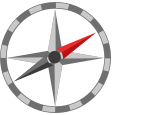**Further Exploration**

- Here is an [app](https://www.mathworks.com/matlabcentral/fileexchange/23697-image-morphology) that lets you apply several morphology-based operations on images of your choice. It includes some of the more advanced operations along with the ones covered in this module.

- [Image Processing Onramp](https://matlabacademy.mathworks.com/details/image-processing-onramp/imageprocessing) is a free interactive tutorial that provides a practical introduction to image processing in MATLAB® in under two hours. In this tutorial, you will apply morphological operations and other simple processing techniques to retrieve images of receipts from a busy camera roll.

## Helper Functions

This function creates an animation to illustrate the erosion and dilation morphological operations on the input binary image `BW` with a neighborhood image (structuring element) `nhood`. The first input `operation` can be set to `"erosion"`, `"dilation"`, `"opening"`, or `"closing"`. The opening operation animates the erosion operation followed by dilation. The closing operation, likewise, animates the dilation operation followed by erosion.

function BWOut = animateMorphology(operation,BW,nhood)

% Settings for image animation to play within the live script
s = settings;
s.matlab.imshow.AlwaysUseFitMagnification.TemporaryValue = true;


% If the operation is opening, perform erosion followed by dilation of the
% result. Display side-by-side
if strcmpi(operation,"opening")
    T = tiledlayout(1,2,"TileSpacing","compact","Padding","compact");
    title(T,"opening")
    nexttile
    BW1 = animateMorphology("erosion",BW,nhood);
    nexttile    
    BWOut = animateMorphology("dilation",BW1,nhood);

% If the operation is opening, perform erosion followed by dilation of the
% result. Display side-by-side
elseif strcmpi(operation,"closing")
    T = tiledlayout(1,2,"TileSpacing","compact","Padding","compact");
    title(T,"closing")
    nexttile
    BW1 = animateMorphology("dilation",BW,nhood);
    nexttile
    BWOut = animateMorphology("erosion",BW1,nhood);

else 

% Convert image to double, get size, and get neighborhood origin
I = im2double(BW);
[M, N] = size(I);

nhood = logical(nhood);
origin = floor((size(nhood)+1)/2);

% Number of pixels to top, bottom, left and right of origin of structuring element
right  = size(nhood,2)-origin(2);
bottom = size(nhood,1)-origin(1);
left   = origin(2)-1;
top    = origin(1)-1;

% Pad the image based on size of structuring element
if strcmpi(operation,"dilation")
    padval = 0;
elseif strcmpi(operation,"erosion")
    padval = 1;
end
I = padarray(I,[bottom right],padval,"post");
I = padarray(I,[top left],padval,"pre");

% Initialize the loop
BWOut = I;
k = 0;

% Loop through the image pixels (rows and columns)
H = imshow(BWOut);
title(operation);

for m = top+1:top+M
    for n = left+1:left+N
        
        % Frame counter
        k = k+1;
        
        % Compute the output pixel value at current location
        window = I(m-top:m+bottom,n-left:n+right);
        if strcmpi(operation,"dilation")
            BWOut(m,n) = max(window(nhood),[],"all");   
        elseif strcmpi(operation,"erosion")
            BWOut(m,n) = min(window(nhood),[],"all"); 
        else
            error('Operation can only be set to "erosion" or "dilation"')
        end
       
        % Generate a mask indicating location of the structuring element on the image
        nhoodMask = padarray(nhood,[m-top-1 n-left-1],0,"pre");
        nhoodMask = padarray(nhoodMask,[size(I,1)-m-bottom size(I,2)-n-right],0,"post");
        
        % Animate the process and display frame for every other iteration
        if mod(k,2)==0
            result = labeloverlay(BWOut,I,"Colormap",[0.5 0.5 0.5],"Transparency",0.5);% output over the original image
            result = labeloverlay(result,nhoodMask,"Colormap",[0 1 0]);                % structuring element position
            result(m,n,:) = uint8(cat(3,0,255,0));                                     % indicate origin of SE
            H.CData = result;                                                          % update image data in the axes
            rectangle("Position",[left+0.5,top+0.5,N,M],"EdgeColor","r");              % show boundary of the image
            drawnow;
        end                
    end
end

% Extract the output image
BWOut = BWOut(top+1:top+M, left+1:left+N);
BWOut = imbinarize(BWOut);
imshow(BWOut)
end
end
